%Beschreibung: 
%Berechnen und plotten der folgenden Größen
%ittleren Leistung P=1/t*sum(y()t^2)
%Spectrum |Y(f)| =sqrt(Re(Y(f))^2 + Im(Y(f))^2))
%PowerSpectrum P(f)=10*log|Y(f)| 
%Phase Spectrum phi(f) =  arctan(Im(Y(f)/Re(Y(f))
%Definition der Konstanten

clf                 %Löschen vorhandene Figures
tol = 1e-6;         %Tolerance für 0-Wert
%Einlesen der Audiodatei und plotten des Signals
[y,fs] = audioread('Testaudio.wav');  
y=mean(y,2);        %Mittelwert der beiden Spuren in der Audio-Datei
N = length(y);      %Anzahl der Abtastpunkte
 
%Abtastzeitpunkte
% Abtastzeiten
dt=1/fs;               %Abtastintervall in der Zeitdomäne
t = (0:dt:N*dt -dt);  
 
subplot(3,1,1), plot(t,y,'LineWidth',1.0), grid; 
title('Satz "Dies ist eine Suchmaschine"')
xlabel('Zeit in (s)')
ylabel('Signal x(t)')

sound(y,fs);
%Berechnung des Spektrum des Zeitsignals
%N     - Zeitdiskrete Werte y(n)
%Y(k)  - Spektrum von y(n)
%Sample frequency k=fs/L
df=fs/N;      %Abtastfreqeunz
Y=fft(y,N); %FFT
Y= fftshift(Y);
 
 
% Betrachte nur positive Frequenzen für das Leistungssprektrum
sampleIndex = 0:N/2-1;
fp= sampleIndex * df; 
 
% Betrag des Spektrums
Yb = abs(Y);
 
%Verschiebung desSpektrums auf die postive Frequenzseite
 %Energie für negative Frequenzen "addieren" durch Multiplikation mit 2
% Yb(N/2): Gleichanteil in der FFT (einfach)
%  Yb(N/2 + 1) - Yb(N): positives Spectrum (mal 2)
 
%das hier hab ich auskommentiert, wegen Warning: P = Yb((N+1)/2:N)/N;
P(2:end) = 2* P(2:end);
P = 10*log10(P.^2);       %Leistung in [db]
    
subplot(3,1,2), plot(fp(1:50:end),P(1:50:end))
xlabel('Frequency in (Hz)')
ylabel('Power Spectrum in (dB)')
title('Leistungsspektrum')
xlim ([0 4000])
hold on
 
disp('Press Return: ')

Press Return: 


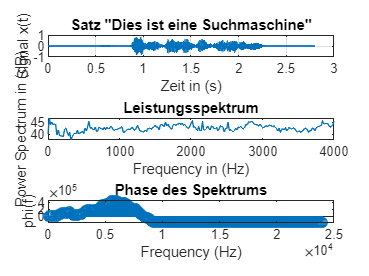

%Press Return: 
 
Y(abs(Y) < tol) = 0;
%das hier hab ich auskommentiert, wegen Warning: phi=unwrap(angle(Y((N+1)/2:N))) * 180/pi; 
 
 
subplot(3,1,3), stem(fp(1:50:end),phi(1:50:end))
ylabel('phi(f)')
xlabel('Frequency (Hz)')
title('Phase des Spektrums')